 
[fname, fpath] = uigetfile( ...
    {'*.csv'}, ...
    'Select file to open' ...
);
wine = readtable([fpath, fname]);

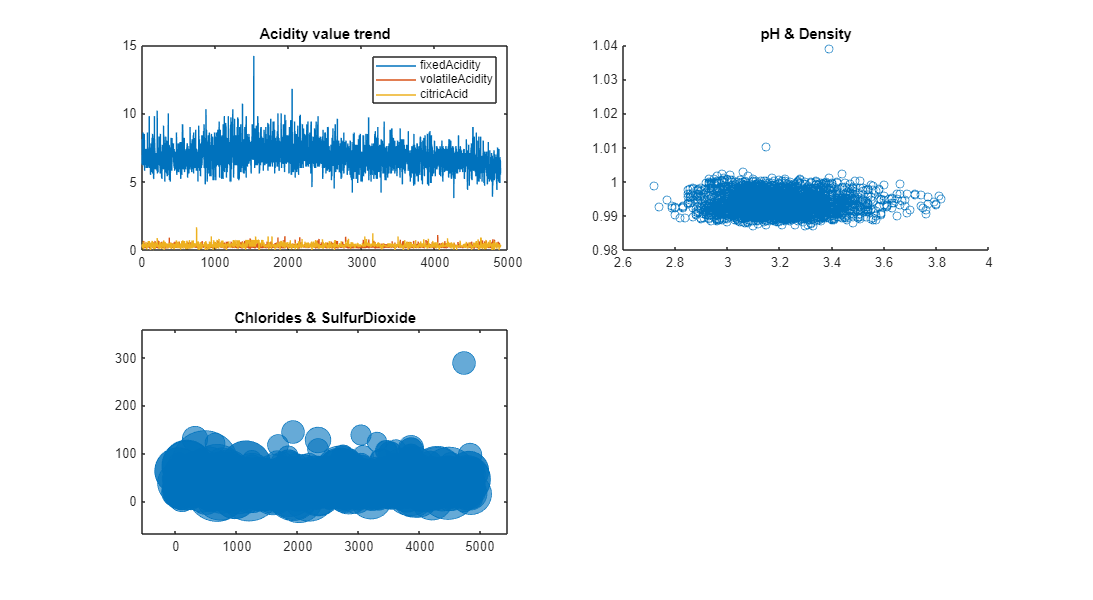


f1 = figure(Name="Plots 1");
f1.Position = [0 0 1920 1080];

subplot(2, 2, 1);
plot(wine{:,1:3});
title("Acidity value trend");
legend(wine.Properties.VariableNames(1:3));

subplot(2, 2, 2);
scatter(wine.pH,wine.density);
title("pH & Density");

subplot(2, 2, 3);
bubblechart(1:1:4898, wine.freeSulfurDioxide, wine.chlorides)
title("Chlorides & SulfurDioxide");

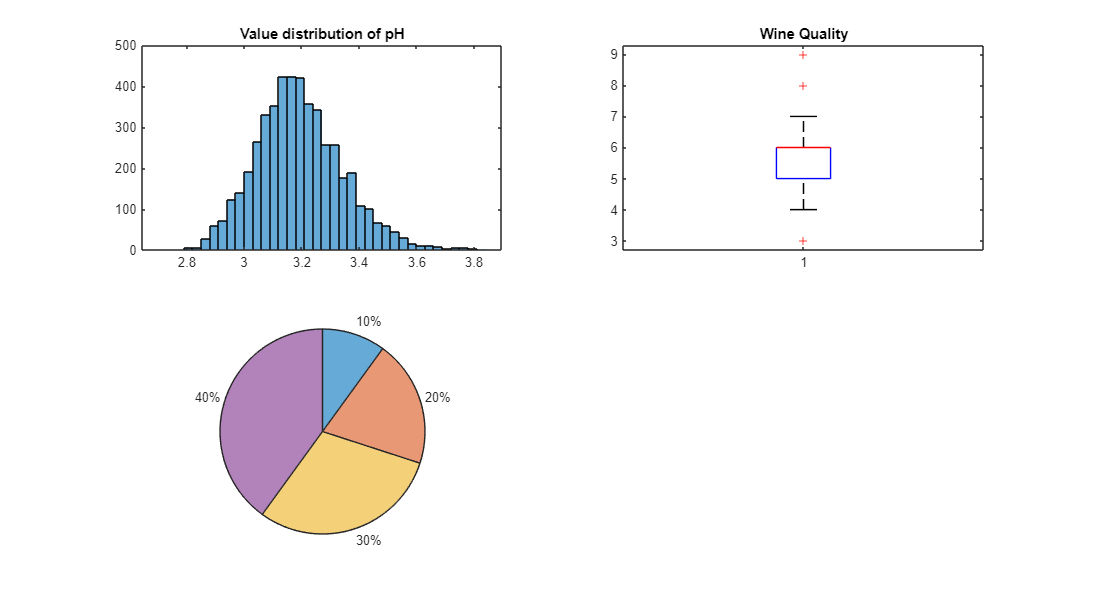

f2 = figure(Name="Plots 2");
f2.Position = [0 0 1920 1080];

subplot(2, 2, 1);
histogram(wine.pH);
title("Value distribution of pH");

subplot(2, 2, 2);
boxplot(wine.quality);
title("Wine Quality");

subplot(2, 2, 3)
data = [1 2 3 4];
piechart(data);

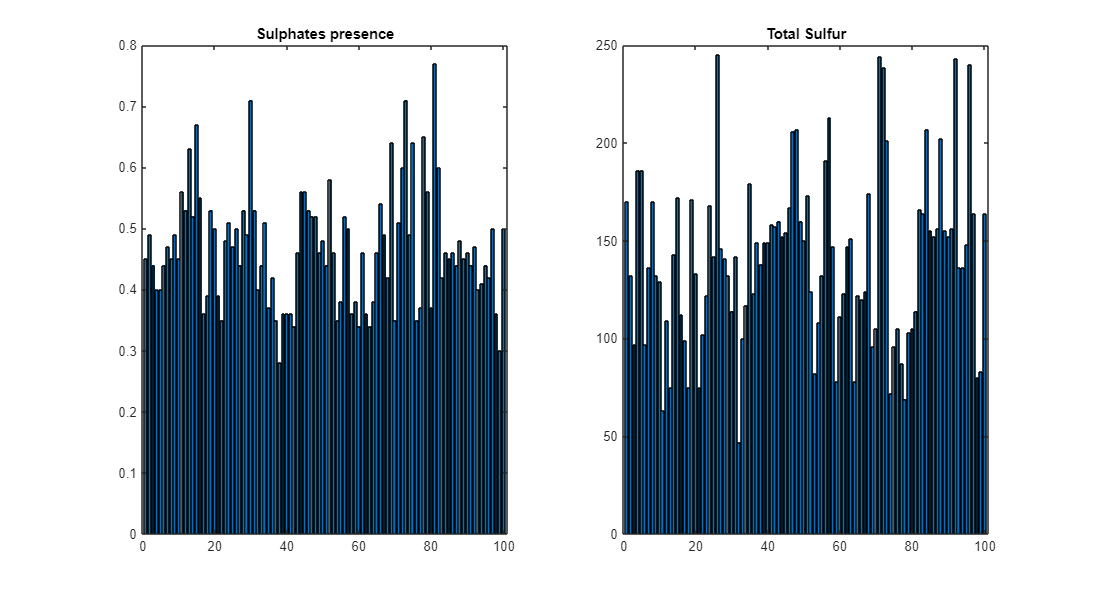

f3 = figure(Name="Plots 3");
f3.Position = [0 0 1920 1080];

subplot(1, 2, 1);
bar(wine.sulphates(1:100));
title("Sulphates presence");

subplot(1, 2, 2);
bar(wine.totalSulfurDioxide(1:100));
title("Total Sulfur");

 
[fname, fpath] = uigetfile( ...
    {'*.csv'}, ...
    'Select file to open' ...
);
IndiaStates = readtable([fpath, fname]);

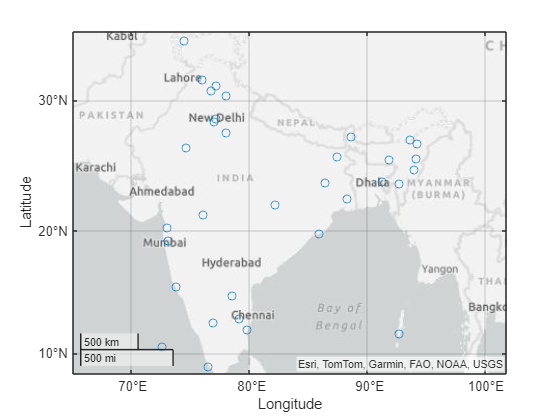

figure
geoscatter(IndiaStates.latitude, IndiaStates.longitude);

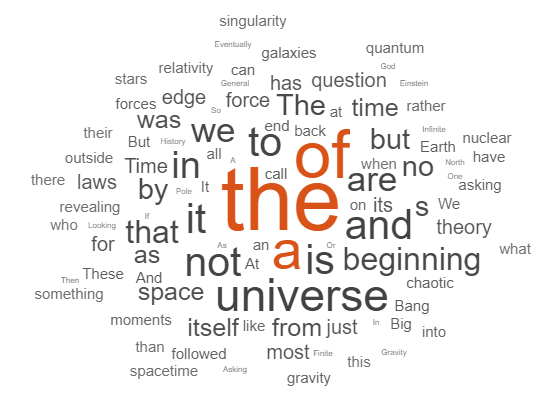

 
[fname, fpath] = uigetfile( ...
    {'*.txt'}, ...
    'Select file to open' ...
);

text_data = fileread([fpath, fname]);
punctuation_characters = ["." "?" "!" "," ";" ":", "—", '“', '”', "’"];
text_data = replace(text_data, punctuation_characters, " ");
words = split(join(text_data));
C = categorical(words);
figure
wordcloud(C);